# Senior Design 2020-2021

## F1TENTH Car Model Controls

% Jonathan Palko 4/6/2021

% References: 
% High Performance Autonomous Racing with RC Cars (Chalmer's Paper)
% More References: https://sites.google.com/site/orcaracer/previous-projects/completed-projects

% Formats all display outputs for values
format shortG

%% Initialization of Car Variables (other than calculated ones)
% Mass of car approximated (6lb/2.72kg)
m_car = 2.72; 
% Gravity (m/s^2)
g = 9.807; 
% Wheel radius (m)
R = 0.097; 

% 54 teeth on the larger gear
N_big = 54; 
% 12 teeth on the smaller gear attached to motor
N_small = 12; 
% Mechanical advantage due to the gear system
N_ratio = N_big/N_small; 

% Distance from COG to left side (m)
bl = 0.1143; 
% Distance from COG to right side (m)
br = 0.1143; 
% Distance from COG to front side (m)
lf = 0.1651; 
% Distance from COG to rear side (m)
lr = 0.1651; 
% Height from bottom of wheel to top part of front (m)
car_height = 0.1321; 

% Moment of Inertia around vehicle (assumed rectangular parallelepiped)
% http://www.tigerquest.com/Mechanical/Strength%20of%20Materials/moment%20of%20inertia.php
% Width of car
inertia_a = bl+br; 
% Height of car
inertia_b = car_height; 
% Length of car
inertia_l = lf+lr; 
% kg*m^2
Iz = (1/12) * m_car * (inertia_a^2 + inertia_l^2); 

% Angular velocity, yaw rate (deg/s)
omega_deg = 4;
omega_rad = deg2rad(omega_deg);

% Drag Calculation and Declaration in Motor Model Section


## Pulling Experimental Log Data

% Using the actual test log

% 1st col = Throttle setpoint (control input u(t))
% 2nd col = RPS
% 3rd col = adjust (braking affect when set from HIGH to 0)
% 4th col = raw AccX
% 5th col = raw AccY
% 6th col = raw AccZ
% 7th col = raw MagX
% 8th col = raw MagY
% 9th col = raw MagZ
% 10th col = raw GyrY

% Trim of the deceleration parts by looking at set throttle
% Only care about the unit step up not braking
% From IMU 1g = 9.81 m/s^2 = 16384 MU

strht_data_10 = readtable('log-10.csv');
strht_data_10 = table2array(strht_data_10);
strht_data_10 = strht_data_10((strht_data_10(:,3) == 0 | strht_data_10(:,3) == 6),:);
% Converting the throttle data into percentages
strht_data_10(:,3) = strht_data_10(:,3) / 60;
strht_data_10(:,1) = strht_data_10(:,1) / 60;
% Converting accel data (mg) to m/s^2
strht_data_10(:,4) = strht_data_10(:,4) .* 0.00981;
strht_data_10(:,5) = strht_data_10(:,5) .* 0.00981;
strht_data_10(:,6) = strht_data_10(:,6) .* 0.00981;

strht_data_15 = readtable('log-15.csv');
strht_data_15 = table2array(strht_data_15);
strht_data_15 = strht_data_15((strht_data_15(:,3) == 0 | strht_data_15(:,3) == 9),:);
% Converting the throttle data into percentages
strht_data_15(:,3) = strht_data_15(:,3) / 60;
strht_data_15(:,1) = strht_data_15(:,1) / 60;
% Converting accel data (mg) to m/s^2
strht_data_15(:,4) = strht_data_15(:,4) .* 0.00981;
strht_data_15(:,5) = strht_data_15(:,5) .* 0.00981;
strht_data_15(:,6) = strht_data_15(:,6) .* 0.00981;

strht_data_20 = readtable('log-20.csv');
strht_data_20 = table2array(strht_data_20);
strht_data_20 = strht_data_20((strht_data_20(:,3) == 0 | strht_data_20(:,3) == 12),:);
% Converting the throttle data into percentages
strht_data_20(:,3) = strht_data_20(:,3) / 60;
strht_data_20(:,1) = strht_data_20(:,1) / 60;
% Converting accel data (mg) to m/s^2
strht_data_20(:,4) = strht_data_20(:,4) .* 0.00981;
strht_data_20(:,5) = strht_data_20(:,5) .* 0.00981;
strht_data_20(:,6) = strht_data_20(:,6) .* 0.00981;

strht_data_25 = readtable('log-25.csv');
strht_data_25 = table2array(strht_data_25);
strht_data_25 = strht_data_25((strht_data_25(:,3) == 0 | strht_data_25(:,3) == 15),:);
% Converting the throttle data into percentages
strht_data_25(:,3) = strht_data_25(:,3) / 60;
strht_data_25(:,1) = strht_data_25(:,1) / 60;
% Converting accel data (mg) to m/s^2
strht_data_25(:,4) = strht_data_25(:,4) .* 0.00981;
strht_data_25(:,5) = strht_data_25(:,5) .* 0.00981;
strht_data_25(:,6) = strht_data_25(:,6) .* 0.00981;

strht_data_30 = readtable('log-30.csv');
strht_data_30 = table2array(strht_data_30);
strht_data_30 = strht_data_30((strht_data_30(:,3) == 0 | strht_data_30(:,3) == 18),:);
% Converting the throttle data into percentages
strht_data_30(:,3) = strht_data_30(:,3) / 60;
strht_data_30(:,1) = strht_data_30(:,1) / 60;
% Converting accel data (mg) to m/s^2
strht_data_30(:,4) = strht_data_30(:,4) .* 0.00981;
strht_data_30(:,5) = strht_data_30(:,5) .* 0.00981;
strht_data_30(:,6) = strht_data_30(:,6) .* 0.00981;

% Resizing and adding any tail end zeros for consistent matrix sizing
maxsize = max([size(strht_data_10(:,1),1),size(strht_data_15(:,1),1),size(strht_data_20(:,1),1),size(strht_data_25(:,1),1),size(strht_data_30(:,1),1)])

maxsize =    303


sizecomp10 = maxsize - size(strht_data_10(:,1),1)

sizecomp10 =      0


sizecomp15 = maxsize - size(strht_data_15(:,1),1)

sizecomp15 =     15


sizecomp20 = maxsize - size(strht_data_20(:,1),1)

sizecomp20 =    153


sizecomp25 = maxsize - size(strht_data_25(:,1),1)

sizecomp25 =    169


sizecomp30 = maxsize - size(strht_data_30(:,1),1)

sizecomp30 =    202



strht_data_10 = [strht_data_10; zeros(sizecomp10, 10)];
strht_data_15 = [strht_data_15; zeros(sizecomp15, 10)];
strht_data_20 = [strht_data_20; zeros(sizecomp20, 10)];
strht_data_25 = [strht_data_25; zeros(sizecomp25, 10)];
strht_data_30 = [strht_data_30; zeros(sizecomp30, 10)];

% Re-assigning adjusted values for easier use (add column in data collection for steering angle)
rawThrottle = [strht_data_10(:,1) strht_data_15(:,1) strht_data_20(:,1) strht_data_25(:,1) strht_data_30(:,1)];
rawRPS = [strht_data_10(:,2) strht_data_15(:,2) strht_data_20(:,2) strht_data_25(:,2) strht_data_30(:,2)];
rawAdjust = [strht_data_10(:,3) strht_data_15(:,3) strht_data_20(:,3) strht_data_25(:,3) strht_data_30(:,3)];
rawAccX = [strht_data_10(:,4) strht_data_15(:,4) strht_data_20(:,4) strht_data_25(:,4) strht_data_30(:,4)];
rawAccY = [strht_data_10(:,5) strht_data_15(:,5) strht_data_20(:,5) strht_data_25(:,5) strht_data_30(:,5)];
rawAccZ = [strht_data_10(:,6) strht_data_15(:,6) strht_data_20(:,6) strht_data_25(:,6) strht_data_30(:,6)];
rawMagX = [strht_data_10(:,7) strht_data_15(:,7) strht_data_20(:,7) strht_data_25(:,7) strht_data_30(:,7)];
rawMagY = [strht_data_10(:,8) strht_data_15(:,8) strht_data_20(:,8) strht_data_25(:,8) strht_data_30(:,8)];
rawMagZ = [strht_data_10(:,9) strht_data_15(:,9) strht_data_20(:,9) strht_data_25(:,9) strht_data_30(:,9)];
rawGyrZ = [strht_data_10(:,10) strht_data_15(:,10) strht_data_20(:,10) strht_data_25(:,10) strht_data_30(:,10)];


## Acceleration & RPS Calculations

% Filtering Velocity Data (Analyzing RPS data, and Acc derived velocity data)
% Only car about acceleration with the straight line motion test
% V_y should equal 0 for the straight line testing

% The angle of the steering wheels from the 90 degree reference. Positive is left, and negative is right with center as 0
% Servo min angle is 50 deg and max its 130 (40 degree change)
% Assume both front wheels have same angle

% Time step used was (64 Hz, ~0.0156 sec)
dt = 0.0156.*ones(size(rawAccX,1),1);
tot_time = zeros(size(dt));

for i = 2:size(dt,1)
    tot_time(i) = tot_time(i-1) + dt(i);
end

% Filtering Acceleration Data (Remove gaussian white noise with variance)
% Only car about acceleration with the straight line motion test
varAccX = [var(rawAccX(:,1)), var(rawAccX(:,2)), var(rawAccX(:,3)), var(rawAccX(:,4)), var(rawAccX(:,5))];
varAccY = [var(rawAccY(:,1)), var(rawAccY(:,2)), var(rawAccY(:,3)), var(rawAccY(:,4)), var(rawAccY(:,5))];
varAccZ = [var(rawAccZ(:,1)), var(rawAccZ(:,2)), var(rawAccZ(:,3)), var(rawAccZ(:,4)), var(rawAccZ(:,5))];

% PID IS NOT MAKING THIS SYSTEM RESPONSE INVALID SINCE PID IS ONLY USED FOR
% BRAKING AND SYSTEM BEHAVIOR TO STEADY STATE IS ALL WE CARE ABOUT


% ALTERNATIVE USE A HIGH PASS FILTER TO FILTER OUT NOISE FREQUENCIES
rawAccX_vx = zeros(size(rawAccX));
rawAccY_vx = zeros(size(rawAccY));
rawAccZ_vx = zeros(size(rawAccZ));

% Instead of filtering the velocity data just use the filtered acceleration data
% Need to do some more intense filtering for accY & accZ noise
filtAccX = smoothdata(rawAccX,'movmedian',10);
filtAccY = smoothdata(rawAccY,'movmedian',10);
filtAccZ = smoothdata(rawAccZ,'movmedian',10);

filtAccX_vx = zeros(size(filtAccX));
filtAccY_vx = zeros(size(filtAccY));
filtAccZ_vx = zeros(size(filtAccZ));

for i = 2:size(rawAccX,1)
    rawAccX_vx(i,:) = rawAccX_vx(i-1,:) + rawAccX(i,:).*dt(i);
    rawAccY_vx(i,:) = rawAccY_vx(i-1,:) + rawAccY(i,:).*dt(i);
    rawAccZ_vx(i,:) = rawAccZ_vx(i-1,:) + rawAccZ(i,:).*dt(i);
    
    filtAccX_vx(i,:) = filtAccX_vx(i-1,:) + filtAccX(i,:).*dt(i);
    filtAccY_vx(i,:) = filtAccY_vx(i-1,:) + filtAccY(i,:).*dt(i);
    filtAccZ_vx(i,:) = filtAccZ_vx(i-1,:) + filtAccZ(i,:).*dt(i);
    
   % There is inherent initial bias in the accelerometer that needs to be accounted for
   % Creating an offset negatively impacted the Vx calculations so offset NOT used
   % MAKE SURE TO NOT INCLUDE THIS FOR ACTIVE DRIVING (ONLY INCLUDED FOR MODELING)
   for j = 1:size(rawAccX,2)
    if (rawAccX_vx(i,j) < 0)        
        rawAccX_vx(i,j) = 0;
        rawAccY_vx(i,j) = 0;
        rawAccZ_vx(i,j) = 0;
        
        filtAccX_vx(i,j) = 0;
        filtAccY_vx(i,j) = 0;
        filtAccZ_vx(i,j) = 0;
    end
   end 
end

% Radius of wheels must be used for coverting RPS to m/s
% Conversion: 1 rev = 2*pi*R (m), 1 rev/sec = (2*pi*R)*(x rev/sec) = (m/s)
% For consistency with matrices we needed to add tail zeros
rawRPS_vx = rawRPS.*(2*pi*R);
filtRPS_vx = smoothdata(rawRPS_vx,'movmean',10);

% RPS Acceleration Calculation
rawRPS_acc = zeros(size(rawRPS_vx));
filtRPS_acc = zeros(size(filtRPS_vx));

for i = 2:size(rawRPS_vx,1)
    rawRPS_acc(i,:) = (rawRPS_vx(i,:) - rawRPS_vx(i-1,:))/dt(i);
    filtRPS_acc(i,:) = (filtRPS_vx(i,:) - filtRPS_vx(i-1,:))/dt(i);
end


## Filtering Comparisons

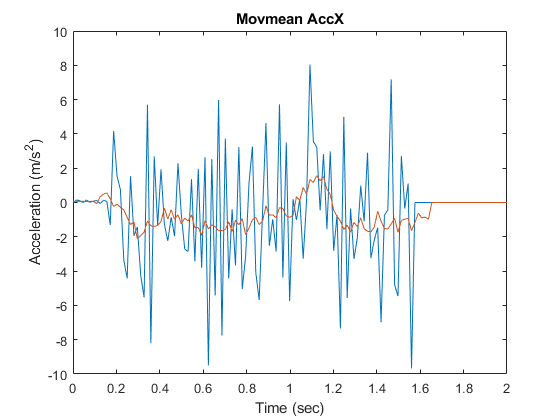

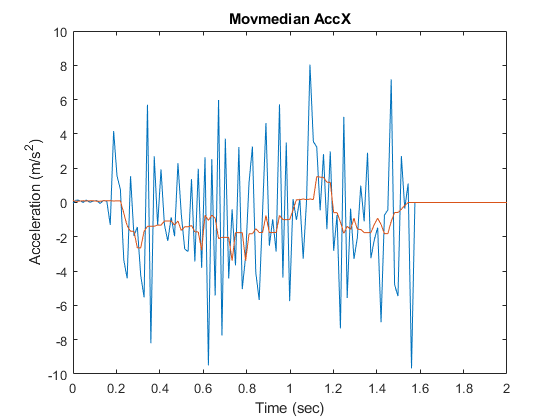

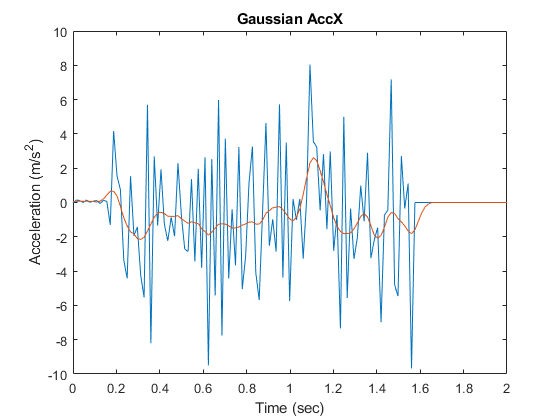

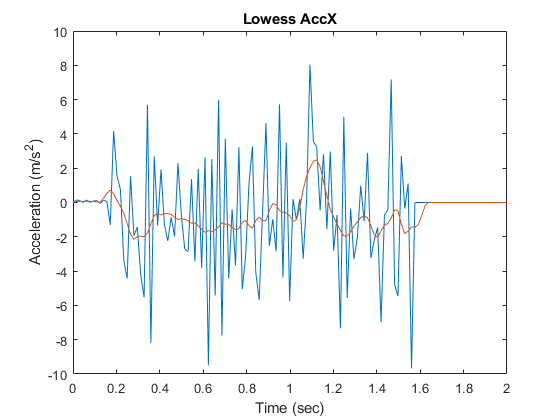

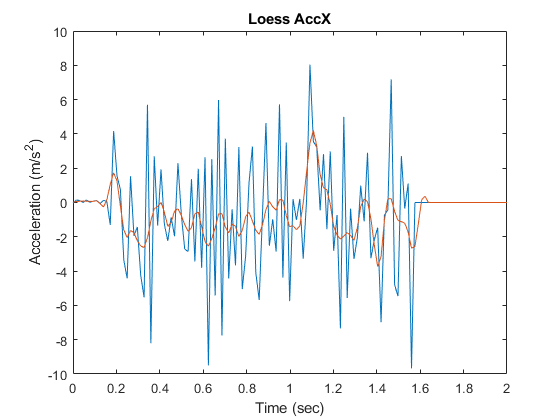

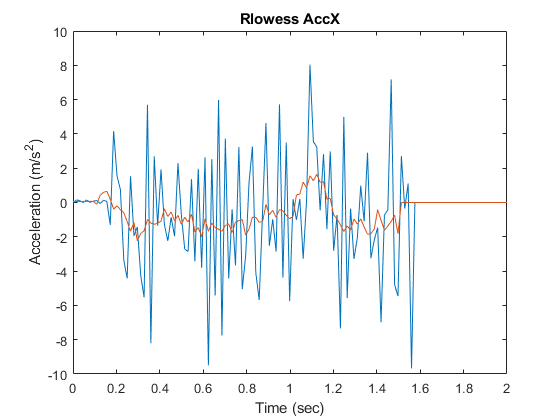

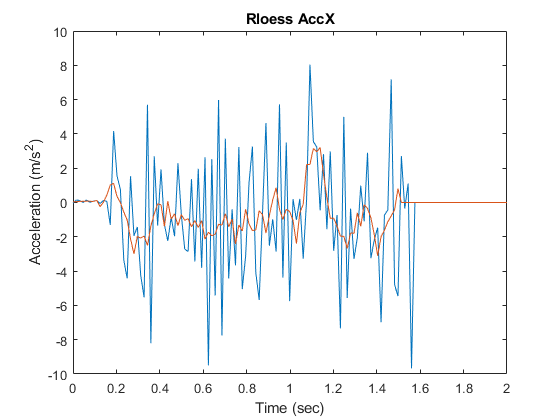

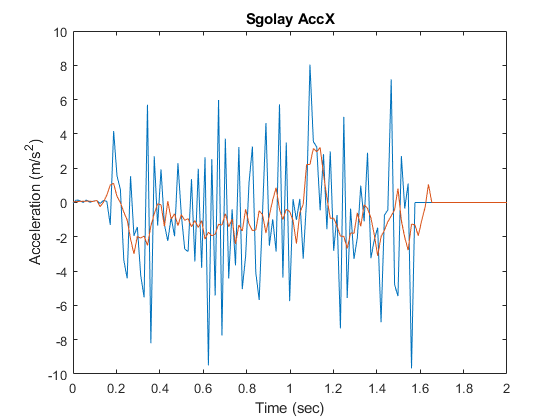

filter_comp = true;

if (filter_comp == true)
    % Array filled with movmean acceleration filtered data
    filt_accY_30 = smoothdata(rawAccY(:,5),'movmean',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Movmean AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'movmedian',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Movmedian AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'gaussian',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Gaussian AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'lowess',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Lowess AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'loess',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Loess AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'rlowess',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Rlowess AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'rloess',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Rloess AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    filt_accY_30 = smoothdata(rawAccY(:,5),'sgolay',10);
    
    figure()
    plot(tot_time, rawAccY(:,5));
    hold on;
    plot(tot_time, filt_accY_30);
    title("Sgolay AccX");
    xlim([0 2]);
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
end

## CSV Testing (Not Run Normally)

% Set to true in order for testing for IMU to show up
test = false;

if(test == true)
    % Only for the Accel problem testing
    strht_data_test = readtable('log-testing.csv');
    strht_data_test = table2array(strht_data_test);
    % Converting accX and accY MU data to m/s^2
    strht_data_test(:,4) = strht_data_test(:,4) / 16.384;
    strht_data_test(:,5) = strht_data_test(:,5) / 16.384;

    testrawAccX = strht_data_test(:,4);
    testrawAccY = strht_data_test(:,5);
    
    tot_time_test = zeros(size(testrawAccX));
    
    for i = 2:size(testrawAccX,1)
        tot_time_test(i) = tot_time_test(i-1) + dt(1);
    end
    
    filt_accX_test = smoothdata(testrawAccX(:,1),'movmean',10);
    filt_accY_test = smoothdata(testrawAccY(:,1),'movmean',10);
    
    figure()
    plot(tot_time_test, testrawAccX(:,1));
    hold on;
    plot(tot_time_test, filt_accX_test);
    title("Movmean AccX");
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
    
    figure()
    plot(tot_time_test, testrawAccY(:,1));
    hold on;
    plot(tot_time_test, filt_accY_test);
    title("Movmean AccY");
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");

end

## RPS Graphs

rps_graphs = false;

if (rps_graphs == true)
    figure()
    plot(tot_time, rawRPS_vx);
    hold on;
    title("RPS Derived Raw V_x");
    legend("10%","15%","20%","25%","30%");
    xlabel("Time (sec)");
    ylabel("Velocity (m/s)");

    figure()
    plot(tot_time, filtRPS_vx);
    hold on;
    title("RPS Derived Filtered V_x");
    legend("10%","15%","20%","25%","30%");
    xlabel("Time (sec)");
    ylabel("Velocity (m/s)");

    figure()
    plot(tot_time, filtRPS_acc);
    hold on;
    title("RPS Derived Filtered AccX");
    legend("10%","15%","20%","25%","30%",'Location','southwest');
    xlabel("Time (sec)");
    ylabel("Acceleration (m/s^2)");
end

## Acceleration Graphs

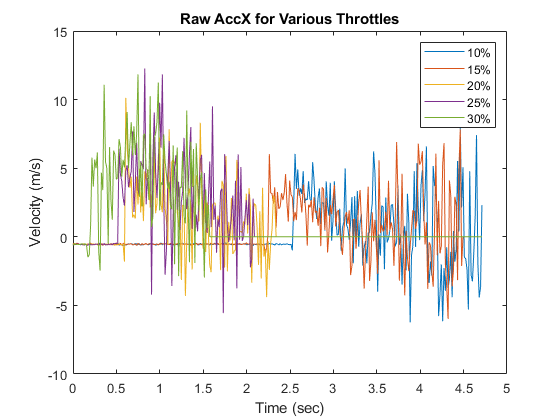

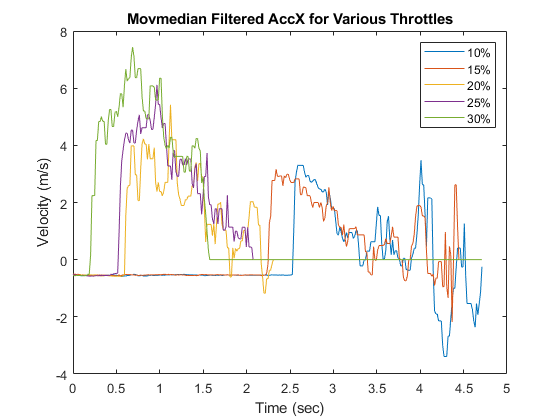

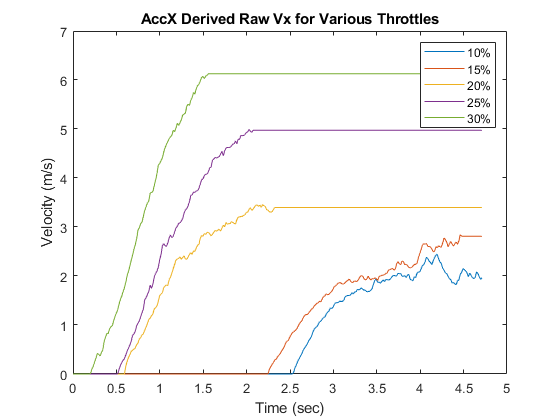

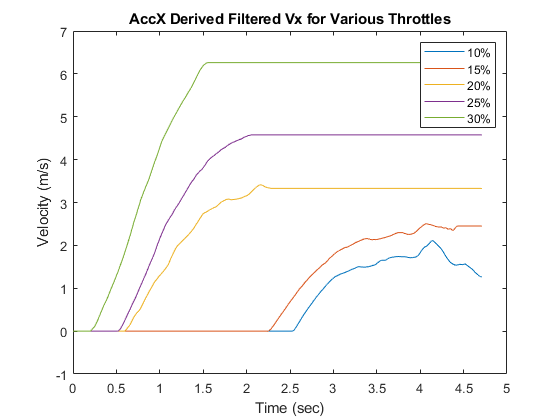

accel_graphs = true;

if (accel_graphs == true)
    figure()
    plot(tot_time, rawAccX);
    hold on;
    title("Raw AccX for Various Throttles");
    legend("10%","15%","20%","25%","30%");
    xlabel("Time (sec)");
    ylabel("Velocity (m/s)");
    
    figure()
    plot(tot_time, filtAccX);
    hold on;
    title("Movmedian Filtered AccX for Various Throttles");
    legend("10%","15%","20%","25%","30%");
    xlabel("Time (sec)");
    ylabel("Velocity (m/s)");
    
    figure()
    plot(tot_time, rawAccX_vx);
    hold on;
    title("AccX Derived Raw Vx for Various Throttles");
    legend("10%","15%","20%","25%","30%");
    xlabel("Time (sec)");
    ylabel("Velocity (m/s)");
    
    figure()
    plot(tot_time, filtAccX_vx);
    hold on;
    title("AccX Derived Filtered Vx for Various Throttles");
    legend("10%","15%","20%","25%","30%");
    xlabel("Time (sec)");
    ylabel("Velocity (m/s)");
end

## Motor Parameter Calculation (Old Version Used RPS Data)

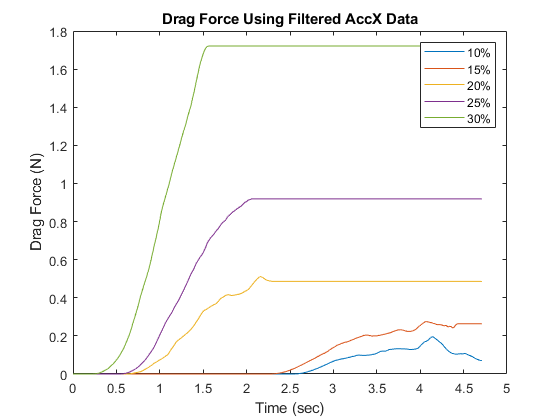

% Straight line motion (steering angle = 0) at varying percent throttles
% Throttle number is out of 60 so 6 = 10% throttle 
% D_0 is the minimal % throttle needed for movement (overcome static friction)
% setD goes 10%, 15%, 20%, 25%, 30%, 35%
D_0 = 0.1;

% For now calculate using the RPS data (Accelerometer data not trusted yet)
% Using Filtered data not Raw data

% Confirmed data values with Alex Cilento via Aerodynamic software at 12.5 m/s
% Density of air in kg/m^3 at 25C and 1atm
p_air = 1.1839; 
% Aerodynamic coefficient of drag (AERODYNAMIC SOFTWARE PROVIDED)
% Cd_without shell = 0.17, Cd_with shell = 0.15
Cd = 0.17; 
% Windward area of the vehicle (m^2) (AERODYNAMIC SOFTWARE PROVIDED)
% A_f without shell = 0.436, A_f with shell = 0.589
A_f = 0.436; 

F_drag = (Cd.*p_air.*A_f.*filtAccX_vx.^2)./2;

figure()
plot(tot_time, F_drag);
hold on;
title("Drag Force Using Filtered AccX Data");
legend("10%","15%","20%","25%","30%",'Location','northeast');
xlabel("Time (sec)");
ylabel("Drag Force (N)");


syms C_m0 C_0 C_1

% [D_0 -1 0; D -1 -v_x; D -1 -v_x] * [C_m0; C_0; C_1] = [0; F_drag; a_x * m * F_drag]
% a_x is momentary acceleration
% motor_par = [C_m0; C_0; C_1]

% 1st row is overcoming static friction (velocity & accel = 0)
% 2nd row is once steady state velocity is reached (accel = 0)
% 3rd row is during the acceleration phase (velocity & accel != 0)

% Used max velocity as steady state since not long enough steady state was
% able to occur. No overshooting either so shouldn't be an issue

% Take velocity and acceleration at total_time = 1.3 for initial testing
% That seems to be a time where all the tests are in the acceleration phase
% This occurs around index point 85 (find((tot_time > 1.31) & (tot_time < 1.32)))

% How will acc_point be defined? --> Acceleration is nonzero
% Don't need 10% throttle (it will result in a singular motor par matrix if used)
% 15% may also be a little inaccurate
acc_point_15 = find(filtAccX(:,2) > 0);
acc_point_20 = find(filtAccX(:,3) > 0);
acc_point_25 = find(filtAccX(:,4) > 0);
acc_point_30 = find(filtAccX(:,5) > 0);

% Solving for parameters (Ax = B --> x = inv(A)*B)
% Can't use the 10% throttle test, since that is the same as minimum throttle
% Using 10% throttle test causes motor_lm to be singular and not invertible
% (Just set those parameters for 10% to 0 for consistent matrix indexing)

motor_par_store = zeros(3,size(rawThrottle,2));
F_rx = zeros(size(filtAccX_vx));

% Arbitray high mean squared value for comparison and storage
E15min = 100000;
E20min = 100000;
E25min = 100000;
E30min = 100000;

sing_track = 0;

% 15% Throttle Parameter Calculations (-1 to remove the final singular matrix which isn't needed)
for i = 1:size(acc_point_15,1)-1
    motor_lm = [D_0, -1, 0; max(rawThrottle(:,2)), -1, -max(filtAccX_vx(:,2)); max(rawThrottle(acc_point_15(i),2)), -1, -filtAccX_vx(acc_point_15(i),2)];
    motor_rm = [0; max(F_drag(:,2)); filtAccX(acc_point_15(i),2) .* m_car * F_drag(acc_point_15(i),2)];
    
    % Same as motor_par = inv(motor_lm) * motor_rm (store 15% in 1st col until shifted after calculations to the 2nd col)
    motor_par = motor_lm\motor_rm;
    
    if(det(motor_lm) == 0)
        sing_track = sing_track + 1;
        fprintf("Singular matrix occured at 15%% throttle acc point: %1d\n",acc_point_15(i));
        fprintf("Time this occured: %1f sec\n", tot_time(acc_point_15(i)));
    end
    
    % Error checking part (keep the one with the least mean square error)
    % Must compute the rear wheel longitudinal force first then calculated vx_dot
    F_rx(:,2) = motor_par(1) .* max(rawThrottle(:,2)) - motor_par(2) - motor_par(3) .* filtAccX_vx(:,2) - F_drag(:,2);
    calc_vxdot = (1/m_car) .* F_rx(:,2);
    
    % Compare calculated vx_dot with measured vx_dot
    E = immse(filtAccX(:,2),calc_vxdot);

    % Checking if new parameters gave lower error and storing new motor par
    if (E15min > E)
        motor_par_store(:,2) = motor_par;
    end
    
    % Storing the new min error for checking the next entry
    E15min = min(E,E15min);
end

Singular matrix occured at 15% throttle acc point: 262


Time this occured: 4.071600 sec



% 20% Throttle Parameter Calculations
for i = 1:size(acc_point_20,1)
    motor_lm = [D_0, -1, 0; max(rawThrottle(:,3)), -1, -max(filtAccX_vx(:,3)); max(rawThrottle(acc_point_20(i),3)), -1, -filtAccX_vx(acc_point_20(i),3)];
    motor_rm = [0; max(F_drag(:,3)); filtAccX(acc_point_20(i),3) .* m_car * F_drag(acc_point_20(i),3)];
    
    % Same as motor_par = inv(motor_lm) * motor_rm (store 15% in 1st col until shifted after calculations to the 2nd col)
    motor_par = motor_lm\motor_rm;
    
    if(det(motor_lm) == 0)
        sing_track = sing_track + 1;
        fprintf("Singular matrix occured at 20%% throttle acc point: %1d\n",acc_point_20(i));
        fprintf("Time this occured: %1f sec\n", tot_time(acc_point_20(i)));
    end
    
    % Error checking part (keep the one with the least mean square error)
    % Must compute the rear wheel longitudinal force first then calculated vx_dot
    F_rx(:,3) = motor_par(1) .* max(rawThrottle(:,3)) - motor_par(2) - motor_par(3) .* filtAccX_vx(:,3) - F_drag(:,3);
    calc_vxdot = (1/m_car) .* F_rx(:,3);
    
    % Compare calculated vx_dot with measured vx_dot
    E = immse(filtAccX(:,3),calc_vxdot);

    % Checking if new parameters gave lower error and storing new motor par
    if (E20min > E)
        motor_par_store(:,3) = motor_par;
    end
    
    % Storing the new min error for checking the next entry
    E20min = min(E,E20min);
end

Singular matrix occured at 20% throttle acc point: 139


Time this occured: 2.152800 sec



% 25% Throttle Parameter Calculations
for i = 1:size(acc_point_25,1)
    motor_lm = [D_0, -1, 0; max(rawThrottle(:,4)), -1, -max(filtAccX_vx(:,4)); max(rawThrottle(acc_point_25(i),4)), -1, -filtAccX_vx(acc_point_25(i),4)];
    motor_rm = [0; max(F_drag(:,4)); filtAccX(acc_point_25(i),4) .* m_car * F_drag(acc_point_25(i),4)];
    
    % Same as motor_par = inv(motor_lm) * motor_rm (store 15% in 1st col until shifted after calculations to the 2nd col)
    motor_par = motor_lm\motor_rm;
    
    if(det(motor_lm) == 0)
        sing_track = sing_track + 1;
        fprintf("Singular matrix occured at 25%% throttle acc point: %1d\n",acc_point_25(i));
        fprintf("Time this occured: %1f sec\n", tot_time(acc_point_25(i)));
    end
    
    % Error checking part (keep the one with the least mean square error)
    % Must compute the rear wheel longitudinal force first then calculated vx_dot
    F_rx(:,4) = motor_par(1) .* max(rawThrottle(:,4)) - motor_par(2) - motor_par(3) .* filtAccX_vx(:,4) - F_drag(:,4);
    calc_vxdot = (1/m_car) .* F_rx(:,4);
    
    % Compare calculated vx_dot with measured vx_dot
    E = immse(filtAccX(:,4),calc_vxdot);

    % Checking if new parameters gave lower error and storing new motor par
    if (E25min > E)
        motor_par_store(:,4) = motor_par;
    end
    
    % Storing the new min error for checking the next entry
    E25min = min(E,E25min);
end

Singular matrix occured at 25% throttle acc point: 133


Time this occured: 2.059200 sec



% 30% Throttle Parameter Calculations (-1 to remove the final singular matrix which isn't needed)
for i = 1:size(acc_point_30,1)-1
    motor_lm = [D_0, -1, 0; max(rawThrottle(:,5)), -1, -max(filtAccX_vx(:,5)); max(rawThrottle(acc_point_30(i),5)), -1, -filtAccX_vx(acc_point_30(i),5)];
    motor_rm = [0; max(F_drag(:,5)); filtAccX(acc_point_30(i),5) .* m_car * F_drag(acc_point_30(i),5)];
    
    % Same as motor_par = inv(motor_lm) * motor_rm (store 15% in 1st col until shifted after calculations to the 2nd col)
    motor_par = motor_lm\motor_rm;
    
    if(det(motor_lm) == 0)
        sing_track = sing_track + 1;
        fprintf("Singular matrix occured at 30%% throttle acc point: %1d\n",acc_point_30(i));
        fprintf("Time this occured: %1f sec\n", tot_time(acc_point_30(i)));
    end
    
    % Error checking part (keep the one with the least mean square error)
    % Must compute the rear wheel longitudinal force first then calculated vx_dot
    F_rx(:,5) = motor_par(1) .* max(rawThrottle(:,5)) - motor_par(2) - motor_par(3) .* filtAccX_vx(:,5) - F_drag(:,5);
    calc_vxdot = (1/m_car) .* F_rx(:,5);
    
    % Compare calculated vx_dot with measured vx_dot
    E = immse(filtAccX(:,5),calc_vxdot);

    % Checking if new parameters gave lower error and storing new motor par
    if (E30min > E)
        motor_par_store(:,5) = motor_par;
    end
    
    % Storing the new min error for checking the next entry
    E30min = min(E,E30min);
end

% fprintf("The index point for acceleration data: %1d\n", acc_point);
fprintf("Motor Parameters [C_m0; C_0; C_1] For Throttles 0.10, 0.15, 0.20, 0.25, & 0.30\n");

Motor Parameters [C_m0; C_0; C_1] For Throttles 0.10, 0.15, 0.20, 0.25, & 0.30


disp(motor_par_store);

            0      0.29609       37.065       37.989       62.406
            0     0.029609       3.7065       3.7989       6.2406
            0     -0.10397      0.93651       1.0441       1.7178




Emin = [E15min E20min E25min E30min];
fprintf("Mean Squared Error for 0.15, 0.20, 0.25, & 0.30\n");

Mean Squared Error for 0.15, 0.20, 0.25, & 0.30


disp(Emin);

       1.3487       1.7158       2.6558        3.578




loc = find(Emin == min(Emin));
% motor_par = motor_par_store(:,loc+1);
motor_par = motor_par_store(:,3);

fprintf("Chosen Motor Parameters [C_m0, C_0, C_1]");

Chosen Motor Parameters [C_m0, C_0, C_1]

disp(motor_par);

       37.065
       3.7065
      0.93651




fprintf("Total number of singular matrices generated: %1d\n", sing_track);

Total number of singular matrices generated: 3


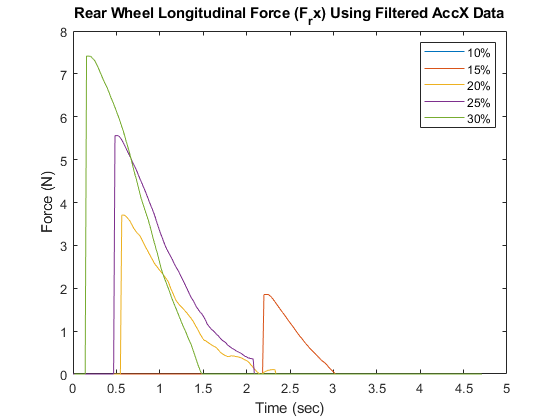


% F_rx = 0 at 10%, max(rawThrottle) for each column will equal set throttle
% since other throttle values are removed previously

F_rx = zeros(size(filtAccX_vx));

for i = 1:size(filtAccX_vx,2)
    F_rx(:,i) = motor_par(1) .* rawThrottle(:,i) - motor_par(2) - motor_par(3) .* filtAccX_vx(:,i) - F_drag(:,i);
end

F_rx(F_rx < 0) = 0;

figure()
plot(tot_time, F_rx);
hold on;
title("Rear Wheel Longitudinal Force (F_rx) Using Filtered AccX Data");
legend("10%","15%","20%","25%","30%",'Location','northeast');
xlabel("Time (sec)");
ylabel("Force (N)");

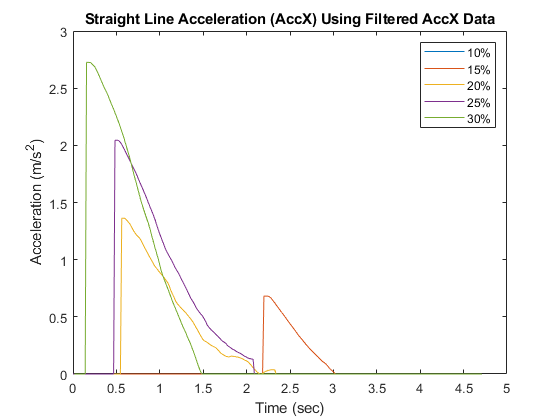


% Simplified equation for system equations of motion
motor_vx_dot = F_rx .* (1/m_car);

motor_vx = zeros(size(motor_vx_dot));

for i = 2:size(motor_vx_dot,1)
    motor_vx(i,:) = motor_vx(i-1,:) + motor_vx_dot(i,:).*dt(i);
end

figure()
plot(tot_time, motor_vx_dot);
hold on;
title("Straight Line Acceleration (AccX) Using Filtered AccX Data");
legend("10%","15%","20%","25%","30%",'Location','northeast');
xlabel("Time (sec)");
ylabel("Acceleration (m/s^2)");

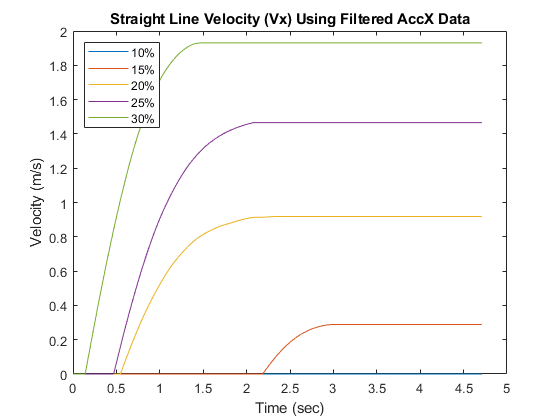


figure()
plot(tot_time, motor_vx);
hold on;
title("Straight Line Velocity (Vx) Using Filtered AccX Data");
legend("10%","15%","20%","25%","30%",'Location','northwest');
xlabel("Time (sec)");
ylabel("Velocity (m/s)");

## Tyre Parameter Calculation

% Integration causes significant data shift as time goes on
% Movmedian filter was compared to other filters and chosen as the best
% option for the omega test data
% omega = strht_data_10(:,7);
% omega_filt = smoothdata(omega,1,'movmedian');
% 
% omega_filt_rad = omega_filt * (pi()/180);

% figure(2)
% plot(tot_time, omega);
% hold on;
% plot(tot_time, omega_filt);

% Has to be in rad/s
% test_circle_radius = v_X./omega_filt_rad; --> Think about frame


## Tyre Model (yes we are using this spelling ;D)

% Need to establish before state space model of car
% Assume d_f, c_f, b_f and d_r, c_r, b_r are just d,c, and b

% Original Description of Forces (don't need to differentiate front and
% rear tyre parameters only the alphas and forces)

% F_fy = d_f * sin(c_f * (b_f * alpha_f))
% F_ry = d_r * sin(c_r * (b_r * alpha_r))
% alpha_f = delta_set - arctan((omega * l_f + v_y)/v_x)
% alpha_r = arctan((omega * l_r - v_y)/v_x)

% F_fy = d * sin(c * (b * alpha_f));
% F_ry = d * sin(c * (b * alpha_r));
% alpha_f = delta_set - arctan((omega * l_f + v_Y)/v_X);
% alpha_r = arctan((omega * l_r - v_Y)/v_X);


## State Space Model of Car

% Omega is the same as yaw rate (psi_dot)
% Yaw angle is psi

% Assume F_fx is 0 since its effect will be indirectly 
% included in the motor equation
F_fx = 0;

% F_rx is defined in the motor model, and F_ry & F_fy are defined in the tyre model

% Steering angle is delta, D is % throttle
% vx_dot = (1/m) * (F_rx - F_fy * sin(delta_set) + m * v_y * omega)
% vy_dot = (1/m) * (F_ry - F_fy * cos(delta_set) - m * v_y * omega)
% omega_dot = (1/I_z) * (F_fy * l_f * cos(delta_set) - F_ry * l_r)
% v_x = v_x
% v_y = v_y
% omega = omega

% For global velocities the local velocities and yaw rates are needed
% These are the global velocities
% X_dot = v_x * cos(psi) - v_y * sin(psi)
% Y_dot = v_x * sin(psi) + v_y * sin(psi)
% psi_dot = omega

% vx_dot = (1/m) * (F_rx - F_fy * sin(delta_set) + m * v_Y * omega);
% vy_dot = (1/m) * (F_ry - F_fy * cos(delta_set) - m * v_Y * omega);
% omega_dot = (1/I_z) * (F_fy * l_f * cos(delta_set) - F_ry * l_r);
% v_x = v_x;
% v_y = v_y;
% omega = omega;

